## Low LEO

### Geometría orbital

Datos de entrada:

h = 650000         % Altura de órbita [m]

h = 1220000

RT = 6371000        % Radio de la Tierra [m]

RT = 6371000

%e = 25;               % Ángulo de elevación [º]
e= [0:5:90]         % Ángulo de elevación [º]

Tenemos el siguiente problema geométrico:

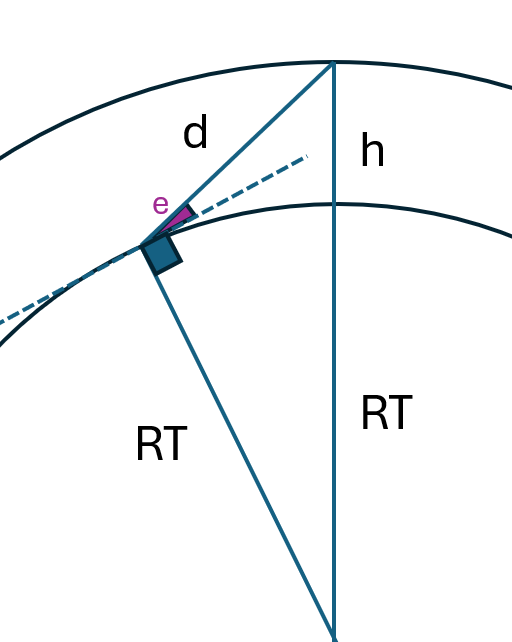

Teorema del Coseno: ${\left(\mathrm{RT}+h\right)}^2 =d^2 +{\mathrm{RT}}^2 -2d\;\mathrm{RT}\;\cos \left(90+e\right)$

a = 1;
b = -2*RT*cos((90+e).*pi/180);
c = -h^2-2*RT*h;
d = (-b+sqrt(b.^2-4*a*c))/(2*a)

d = 2.2353e+06

Teorema del Seno: $\frac{\left(\mathrm{RT}+h\right)}{\sin \;\left(90+e\right)}=\frac{\mathrm{RT}}{\sin \left(\mathrm{alfa}\right)}$

alfa = asin(RT/(RT+h)*sin((90+e)*pi/180))*180/pi

alfa = 49.5214

El ángulo de visión del satélite es: 

fov = 2*alfa

fov = 99.0429

Teorema del Seno: $\frac{\left(\mathrm{RT}+h\right)}{\sin \;\left(90+e\right)}=\frac{d}{\sin \left(\mathrm{gamma}\right)}$

gamma = asin(d/(RT+h).*sin((90+e)*pi/180))*180/pi

gamma = 15.4786

El ángulo máximo de separación de dos satélites consecutivos en órbita (True Anomaly) para que haya conectividad continua (se toquen los bordes de las huellas) es de:

TAmax=2*gamma

TAmax = 30.9571

Y el radio de la huella en la superficie, suponiendo huella circular y apuntando a nadir:

beta = 90-alfa

beta = 40.4786

r = d.*sin(alfa*pi/180)

r = 1.7003e+06

Ahora ploteamos en una gráfica cómo varían los valores con el ángulo de elevación del terminal:

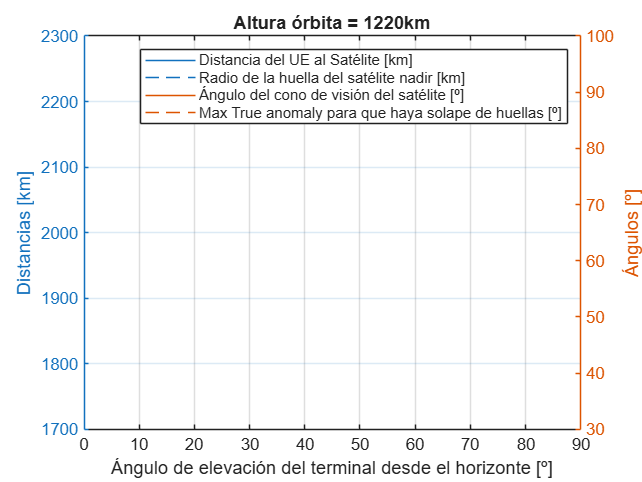

figure;
yyaxis left;
plot(e, d/1000);
hold on;
plot(e, r/1000);
hold on;
ylabel("Distancias [km]")
yyaxis right;
plot(e, fov);
hold on;
plot(e, TAmax);
xlim([0 90]);
grid on;
title("Altura órbita = 1220km");
ylabel("Ángulos [º]")
xlabel("Ángulo de elevación del terminal desde el horizonte [º]");
legend("Distancia del UE al Satélite [km]", "Radio de la huella del satélite nadir [km]",  "Ángulo del cono de visión del satélite [º]", "Max True anomaly para que haya solape de huellas [º]")

## **Elevación máxima del arco de circunferencia GEO**

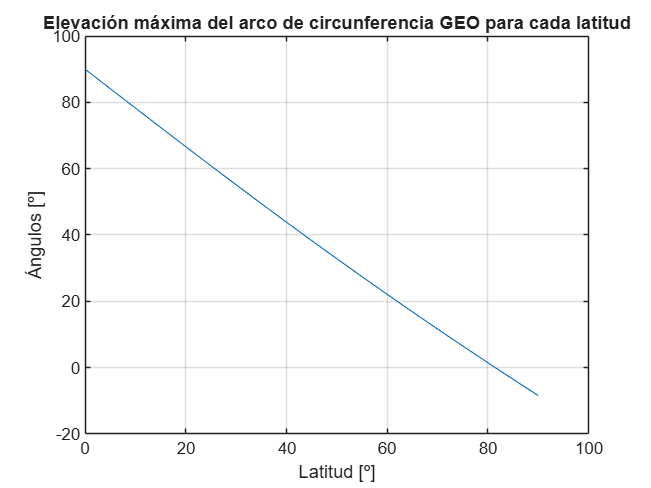

RT = 6371000;
h = 36500000;
Lat = [0:5:90];

x=sqrt((RT+h)^2 + RT^2 - 2*RT*(RT+h)*cos(Lat*pi/180));
eArcGEO = acos((-(RT+h)^2 + RT^2 + x.^2)./(2*RT*x))*180/pi -90;

figure;
plot(Lat, eArcGEO);
grid on;
ylabel("Ángulos [º]");
xlabel("Latitud [º]");
title("Elevación máxima del arco de circunferencia GEO para cada latitud");